# Modelowanie i symulacja w programie MATLAB cz.2

## Jan Rosa 410269 AiR

## Zad 1

### Zad a

 Utwórz m-skrypt wczytujący dane z pliku daneP.csv a następnie realizującego wizualizację danych na wykresie typu plot (każda zmienna na osobnym wykresie). Dodaj do każdego wykresu osobny tytuł. - Wskazówka: użyj import wizarda do importu danych, następnie wygeneruj m-funkcję do importu danych i wykorzystaj ją w swoim m-skrypcie

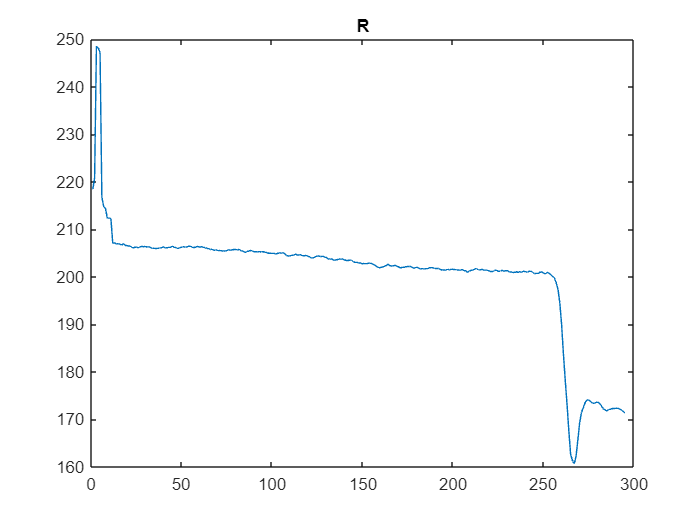

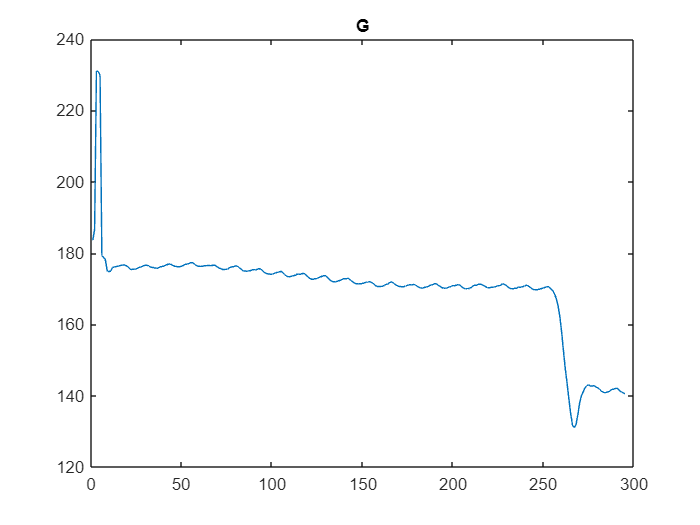

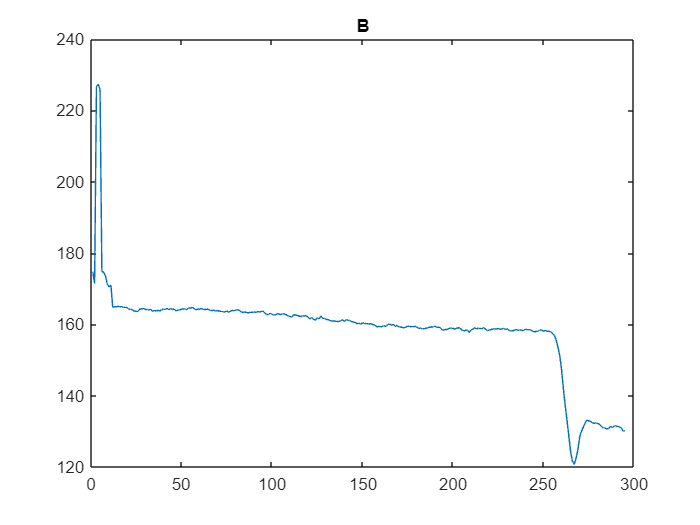

import1

Kod m-skryptu:

daneP = readmatrix('daneP.csv');

R = daneP(:, 1);

G = daneP(:, 2);

B = daneP(:, 3);

figure

subplot(1, 3, 1)

plot(R)

title("R")

subplot(1, 3, 2)

plot(G)

title("G")

subplot(1, 3, 3)

plot(B)

title("B")

### Zad b

Z zaimportowanych danych wybierz taki fragment, na którym widoczny jest sygnał okresowy. Utwórz nową zmienną zawierającą wybrany fragment sygnału i zwizualizuj ją na osobnym oknie wykresu. - Wskazówka: Przyglądnij się wykresowi każdej składowej i wybierz taką, na której okresowość jest najlepiej widoczna. Następnie, przy pomocy indeksowania, wybierz fragment pomijając zakłócenia na początku i na końcu sygnału.

okres = daneP(100:230,:)

okres =   204.9200  174.0600  162.8000
  204.9200  174.2500  162.6100
  204.7800  174.4000  162.6900
  204.8800  174.6200  162.9900
  205.0600  174.6600  162.8400
  204.9700  174.8800  162.7600
  205.0600  174.5200  162.9800
  204.8600  173.9700  162.8400
  204.4700  173.5600  162.6800
  204.3800  173.3500  162.3200


czas_pr = 1/900

czas_pr = 0.0011

time = 0:czas_pr:130*czas_pr

time =          0    0.0011    0.0022    0.0033    0.0044    0.0056    0.0067    0.0078    0.0089    0.0100    0.0111    0.0122    0.0133    0.0144    0.0156    0.0167    0.0178    0.0189    0.0200    0.0211    0.0222    0.0233    0.0244    0.0256    0.0267    0.0278    0.0289    0.0300    0.0311    0.0322    0.0333    0.0344    0.0356    0.0367    0.0378    0.0389    0.0400    0.0411    0.0422    0.0433    0.0444    0.0456    0.0467    0.0478    0.0489    0.0500    0.0511    0.0522    0.0533    0.0544


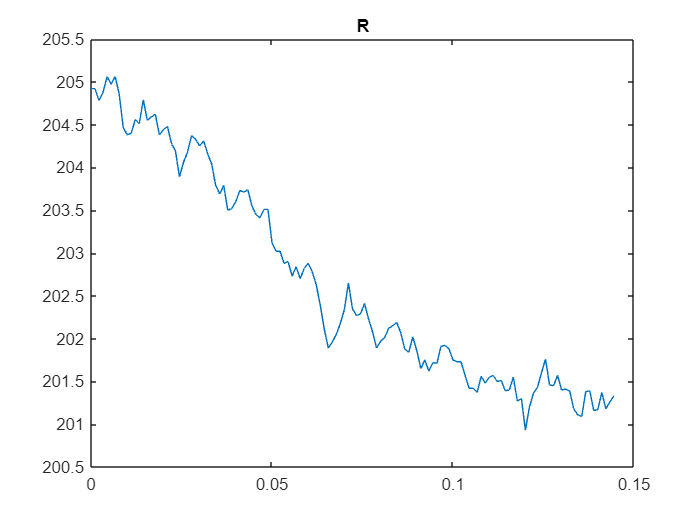

figure("Name","R")
plot(time, okres(:, 1))
title("R")

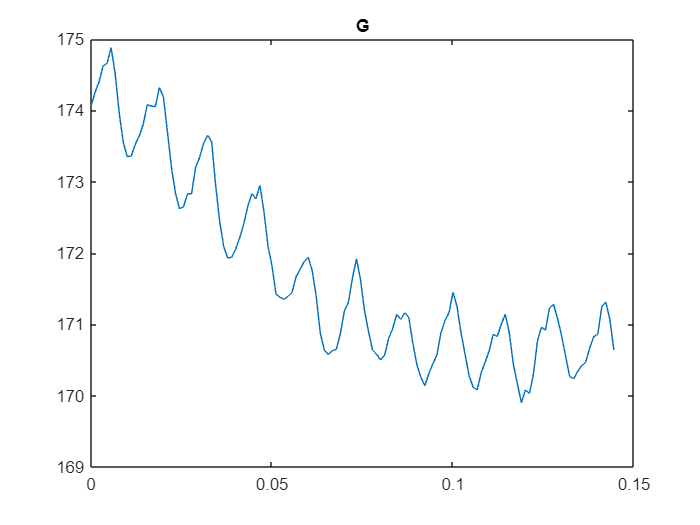

figure("Name","G")
plot(time, okres(:, 2))
title("G")

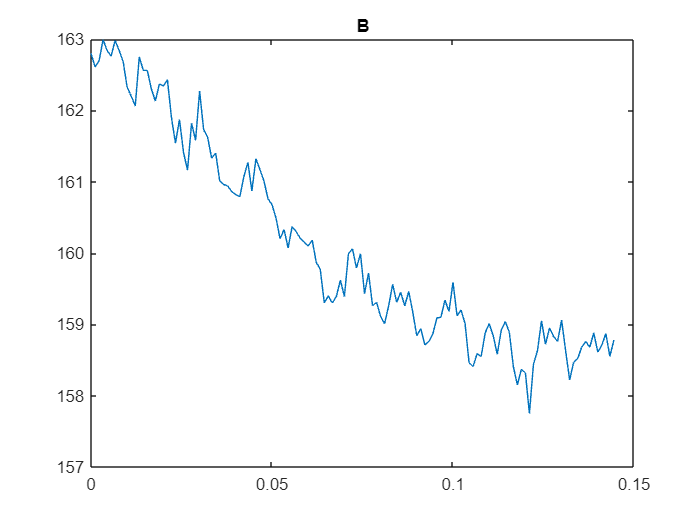

figure("Name","B")
plot(time, okres(:, 3))
title("B")

### Zad c

Z wybranego fragmentu sygnału, usuń trend poprzez dopasowanie krzywej wielomianowej. Dobierz stopień wielomianu jak najmniejszego stopnia przy zachowaniu jak najmniejszego błędu dopasowania (funkcja norm). Do wykresu z poprzedniego punktu dodaj linię dopasowanego trendu (inny kolor). Utwórz nowy wykres zawierający sygnał z usuniętym trendem. - Wskazówka – możesz zrealizować dopasowanie przy pomocy narzędzia Basic Fitting Tool, a następnie wygenerować m-kod i wybrać z niego potrzebne fragmenty analizy sygnału

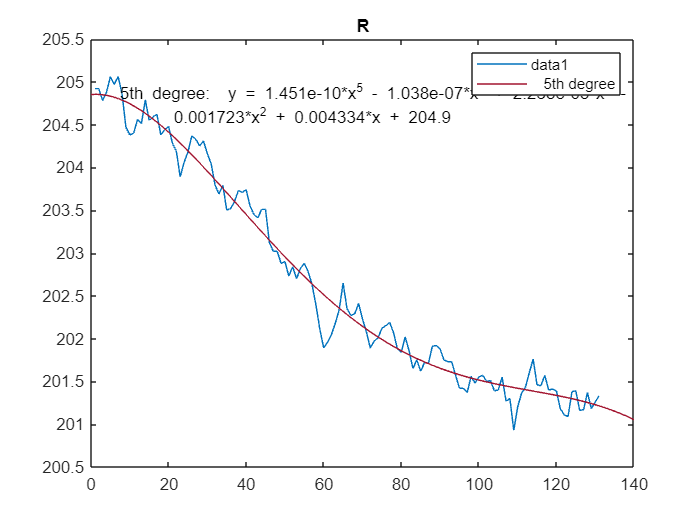

figure
R_createfigure(okres(:, 1));

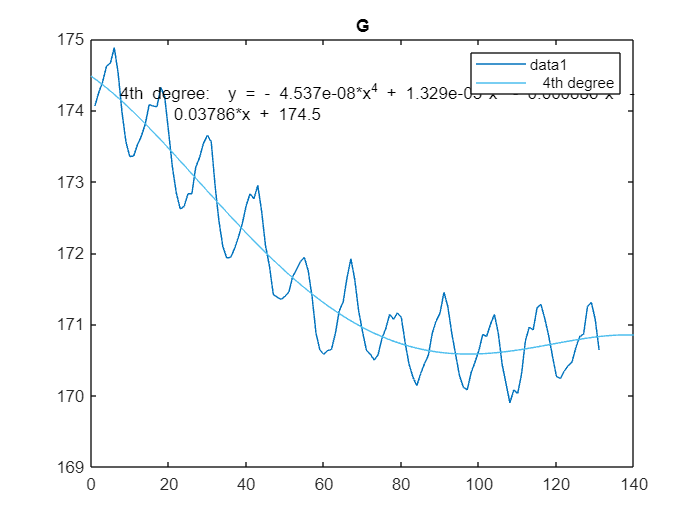

figure
G_createfigure(okres(:, 2));

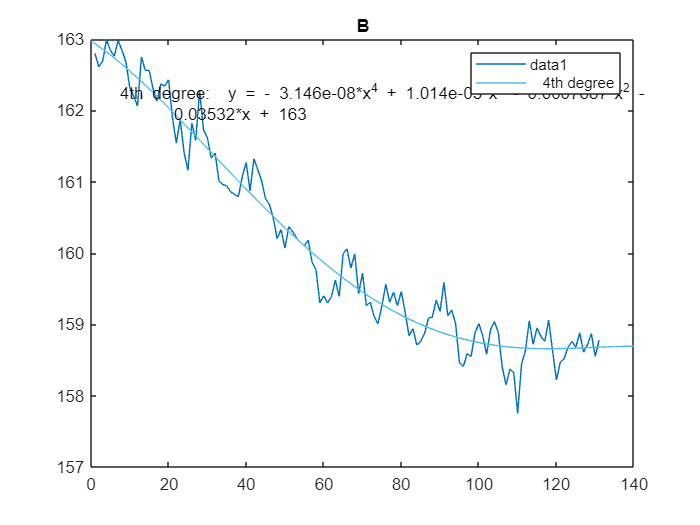

figure
B_createfigure(okres(:, 3));

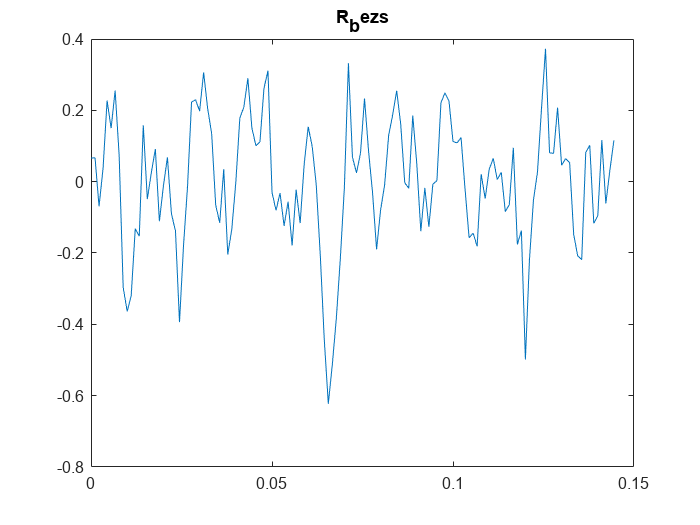

R_szum = polyval(polyfit(time, okres(:, 1), 5), time)';
G_szum = polyval(polyfit(time, okres(:, 2), 4), time)';
B_szum = polyval(polyfit(time, okres(:, 3), 2), time)';

%figure("Name","R poly")
%plot(R_szum)
%title("R poly")
%figure("Name","G poly")
%plot(G_szum)
%title("G poly")
%figure("Name","B poly")
%plot(B_szum)
%title("B poly")
R_bezs = okres(:,1) - R_szum;
G_bezs = okres(:,2) - G_szum;
B_bezs = okres(:,3) - B_szum;

figure
plot(time, R_bezs)
title("R_bezs")

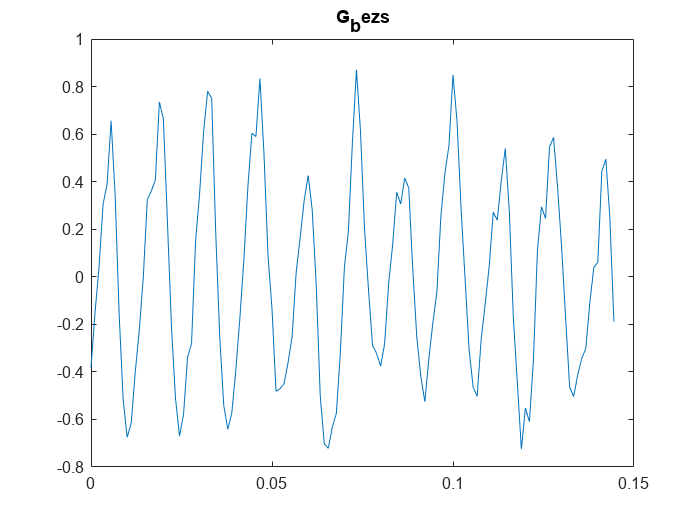

figure
plot(time, G_bezs)
title("G_bezs")

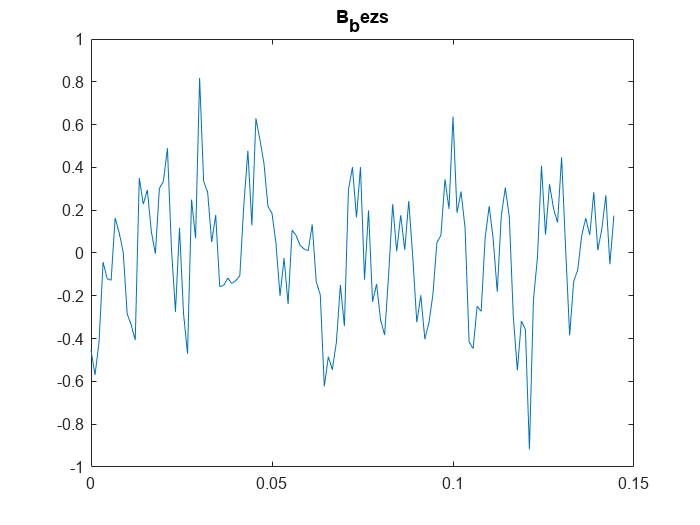

figure
plot(time, B_bezs)
title("B_bezs")

Zad d

Znajdź częstotliwość charakterystyczną sygnału. Sformatuj wykres dodając do niego w sposób programowy: opisy osi x,y i tytuł wykresu. Dodaj do wykresu punkt w miejscu maksimum (częstotliwość charakterystyczna) oraz opis informujący o wartości częstotliwości tego maksimum. - Wskazówka: użyj funkcji fft (patrz przykład w dokumentacji) z częstotliwością próbkowania odczytaną z pliku daneP.csv - Aby dodać do wykresu opis wykorzystaj funkcję text oraz sformatuj tekst przy pomocy funkcji sprintf.

R_fft = abs(fft(R_bezs));
G_fft = abs(fft(G_bezs));
B_fft = abs(fft(B_bezs));
fq = 0:1/czas_pr:66/czas_pr-1

fq =            0         900        1800        2700        3600        4500        5400        6300        7200        8100        9000        9900       10800       11700       12600       13500       14400       15300       16200       17100       18000       18900       19800       20700       21600       22500       23400       24300       25200       26100       27000       27900       28800       29700       30600       31500       32400       33300       34200       35100       36000       36900       37800       38700       39600       40500       41400       42300       43200       44100


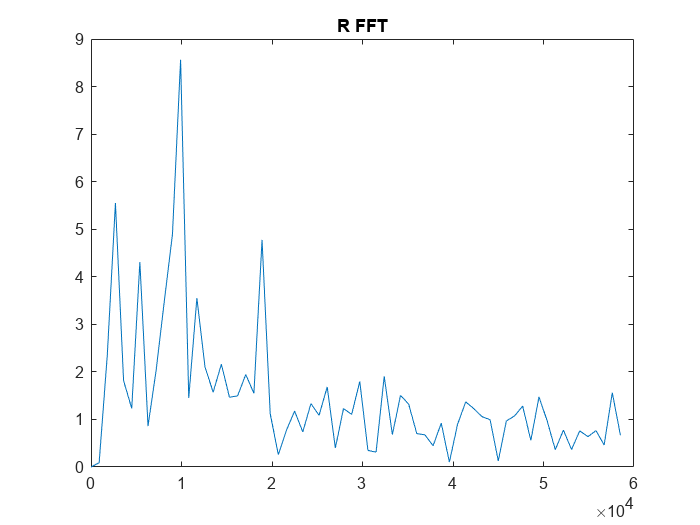

figure
plot(fq, R_fft(1:66))
title("R FFT")

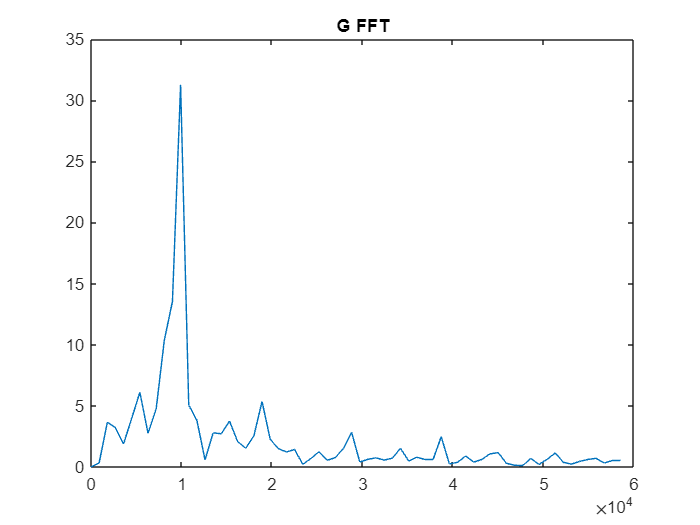

figure
plot(fq, G_fft(1:66))
title("G FFT")

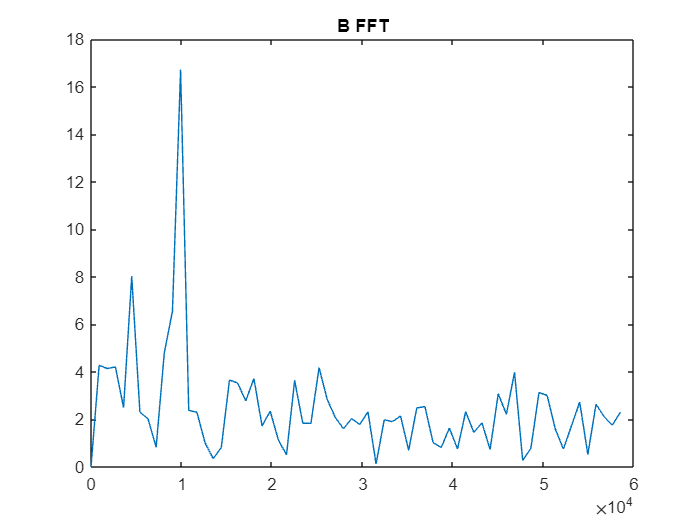

figure
plot(fq, B_fft(1:66))
title("B FFT")

Zad e

Uzupełnij m-plik o komentarze i dokumentacje. Wygeneruj raport w formacie HTML

%przykładowy komentarz
%dokumentacja znajduje się w polach tekstowych LiveScript
%%Raport wygenerowany przez opcje w menu: Safe as

## Zad 2

Zad a

Przy pomocy polecenia randn wygeneruj tablicę 3x3 liczb pseudolosowych R o rozkładzie normalnym (średnia 0 i odchylenie standardowe). Następnie utwórz zmienną A jako typ UINT32, zawierającą liczbę 100. Pomnóż zmienną R przez A, odpowiednio dostosowując typy danych. Rezultat (zmienna B) powinna być typu UINT32. Zwróć uwagę czy rezultaty mnożenia są poprawne ! W sprawozdaniu zanotuj liczbę bajtów potrzebną do zapamiętania jednej liczby typu double oraz jednej liczby typu UINT32 (wskazówka – skorzystaj z polecenie whos).

R = normrnd(0, 1, 3, 3)

R =    -0.8095    0.3252   -1.7115
   -2.9443   -0.7549   -0.1022
    1.4384    1.3703   -0.2414


A = uint32(100)

A = uint32
100

B = uint32(R * double(A))

B = 3×3 uint32 matrix
     0    33     0
     0     0     0
   144   137     0


Jeżeli przed przekształceniem na uint32 liczba była dodatnia to wynik jest zaokrągleniem liczby, jeśli była ujemna to wynik jest równy 0

double zawiera 8 bajtów

uint32 zawiera 4 bajty

Zad b

Utwórz dwie tablice znakowe zawierające teksty: „ćwiczenie 2” oraz „laboratorium 1”. Połącz te dwie tablice (wskazówka – skorzystaj z polecenia strvcat)

cw = 'ćwiczenie 2'

cw = 'ćwiczenie 2'

lab = 'laboratorium 1'

lab = 'laboratorium 1'

joined = strvcat(cw, lab)

joined = 2×14 char array
    'ćwiczenie 2   '
    'laboratorium 1'


Zad c

Utwórz tablicę znakową str1 zawierającą tekst „Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud”. Znajdź indeksy słów zaczynających się na literę „b”, kończących na literę „d” i nie zawierających litery „u”. Wskazówka – skorzystaj z wyrażeń regularnych – dokumentacja do polecenia regexp

str1 = 'Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud'

str1 = 'Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud'

szuk = 'b+[^u]+d'

szuk = 'b+[^u]+d'

[a, b, c] = regexp(str1, szuk, "start")

a = 35

b = 70

c = 1×1 cell array
    {0×0 double}


Zad d

Utwórz tablicę komórkową o rozmiarze 2x2 zawierającą następujące dane jak na rysunku poniżej. Wybierz z tablicy komórkowej, tablicę liczb pseudolosowych znajdującą się w komórce 2-wiersz, 1- kolumna, dodaj do niej wartość 100, a rezultat zapisz w to samo miejsce do tablicy komórkowej. 

incel = rand(3,3);
d2 = {123, "abcd"; incel, 0.1}

d2 = 2×2 cell array
    {[     123]}    {["abcd"]}
    {3×3 double}    {[0.1000]}


Zad e

Oblicz całkę oznaczoną w przedziale 𝑥 ∈ (−2,2) z funkcji 𝑓(𝑥) = 𝑥 2 − 2 ∙ 𝑥 + 4 i narysuj jej wykres dla tego przedziału. Wskazówka – zdefiniuj funkcję przy pomocy uchwytu do funkcji, wykorzystaj funkcję quad oraz fplot.

f = @(x) x.^2 - 2.*x + 4

f = function_handle with value:
    @(x)x.^2-2.*x+4


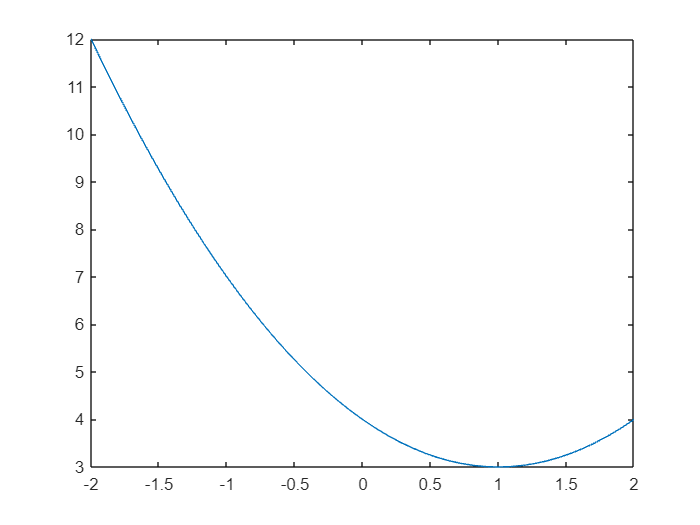

fplot(f, [-2, 2])

integral(f, -2, 2)

ans = 21.3333

Zad f

Utwórz typ danych tabelaryczny (table) zawierający dane jak na rysunku poniżej. Wyeksportuj dane z tabeli do pliku CSV. Wskazówka – sprawdź w systemie pomocy jak definiować nazwy kolumn oraz wierszy. Liczby do tabeli wygeneruj losowo. Skorzystaj z polecenia writetable

Matematyka = randi(100,5,1);
Fizyka = randi(100,5,1);
Chemia = randi(100,5,1);
tablica = table(Matematyka, Fizyka, Chemia);
tablica.Row = ["Rafał", "Monika", "Paweł", "Elżbieta", "Mirek"]

tablica = 5×3 table
                Matematyka    Fizyka    Chemia
                __________    ______    ______

    Rafał           68          96        26  
    Monika          66          35        51  
    Paweł           17          59        70  
    Elżbieta        12          23        90  
    Mirek           50          76        96  
